# Experiment 1

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

## Part1: stem and plot functions

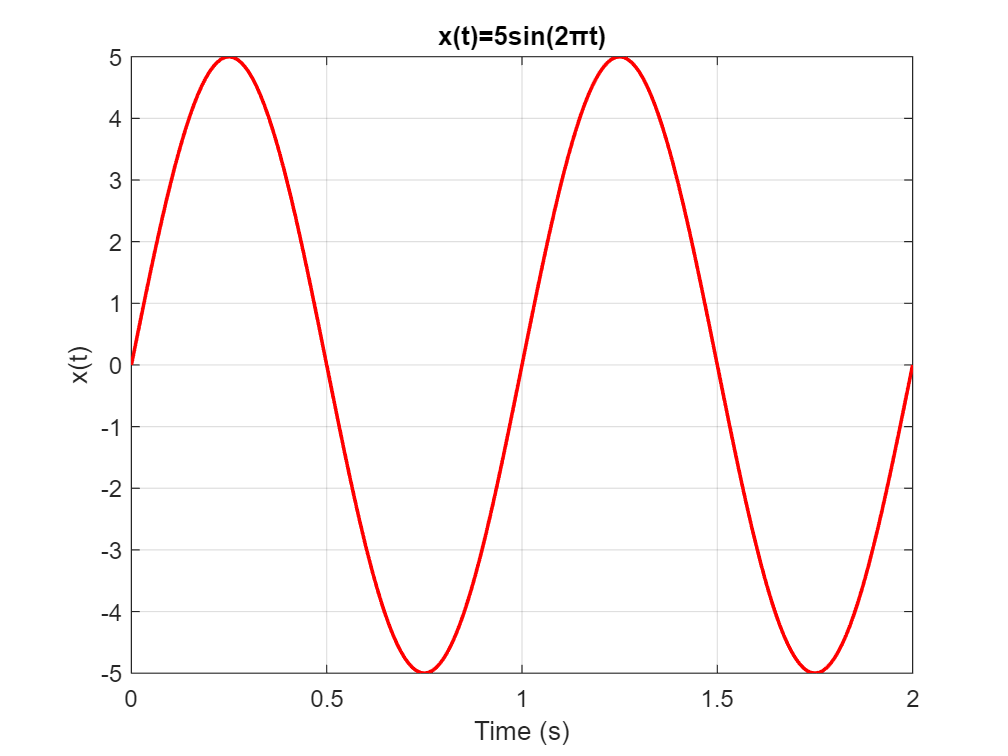

t = 0:0.01:2;
N = length(t);
x = 5*sin(2*pi*t);
figure("Name","sine function using plot");
plot(t, x, LineWidth=1.5, Color='r');
grid on;
title('x(t)=5sin(2\pit)');
xlabel('Time (s)');
ylabel('x(t)');

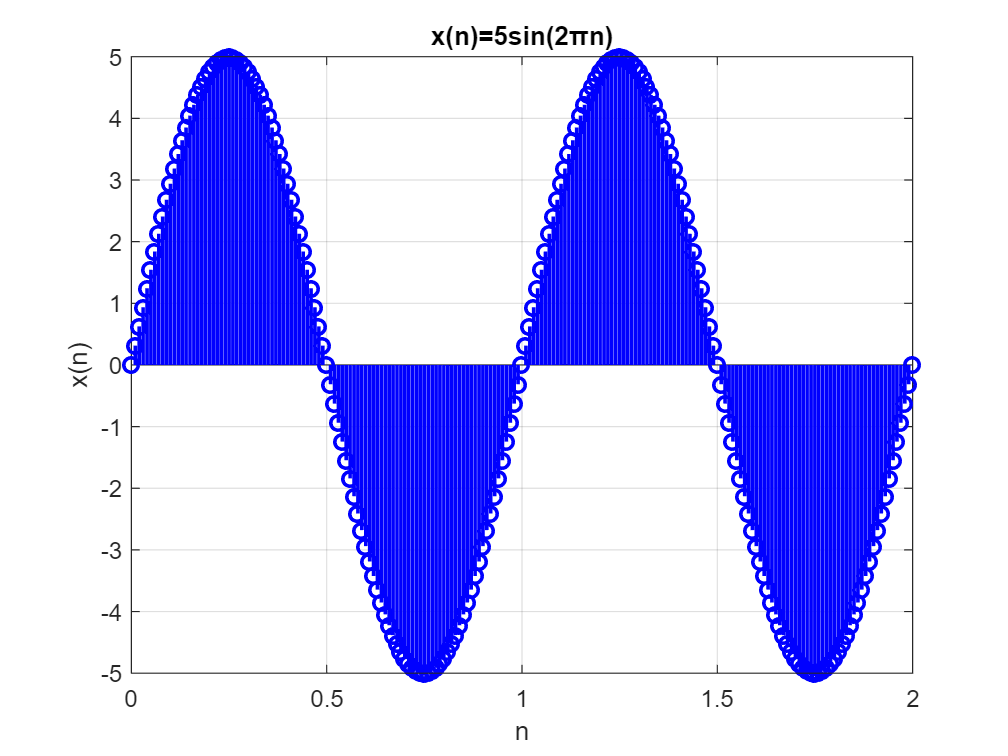

figure("Name","sine function using stem");
stem(t, x, LineWidth=1.5, Color='b');
grid on;
title('x(n)=5sin(2\pin)');
xlabel('n');
ylabel('x(n)');

## Part2: subplot

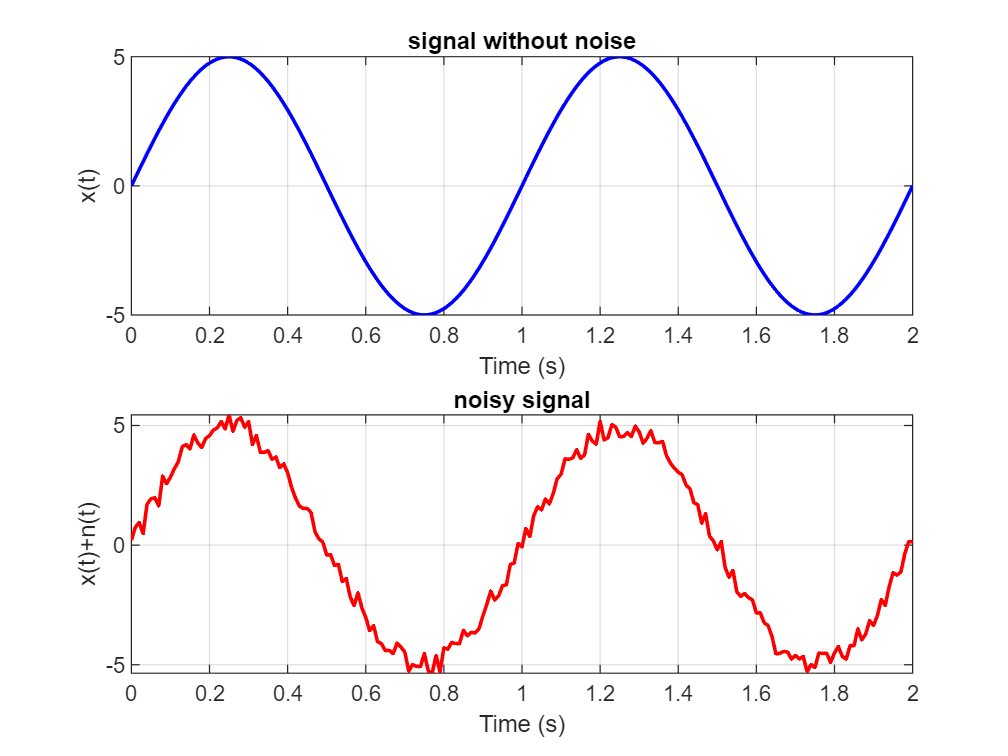

y = rand(1,N)-0.5;
noisy_x = x + y;
figure("Name","plot x and noisy_x plot");
subplot(2,1,1);
plot(t,x, 'b', 'LineWidth', 1.5);
grid on;
title('signal without noise');
xlabel('Time (s)');
ylabel('x(t)');
subplot(2,1,2);
plot(t,noisy_x,  'r', 'LineWidth', 1.5);
grid on;
title('noisy signal');
xlabel('Time (s)');
ylabel('x(t)+n(t)');

## Part3: conv function

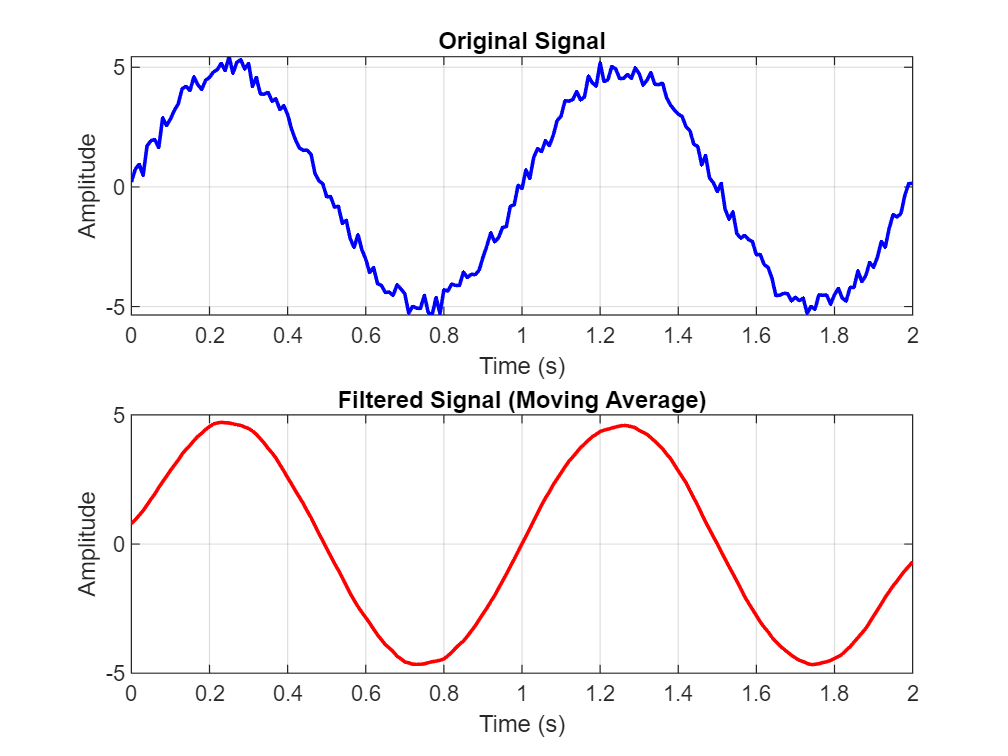

M1 = 0; 
M2 = 20;
filter_length = M2 + M1 - 1;  
moving_avg = ones(1, filter_length) / filter_length;  

conv_result = conv(noisy_x, moving_avg, 'same');  

figure("Name","convolution");
subplot(2,1,1);
plot(t, noisy_x, 'b', 'LineWidth', 1.5);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, conv_result, 'r', 'LineWidth', 1.5);
title('Filtered Signal (Moving Average)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

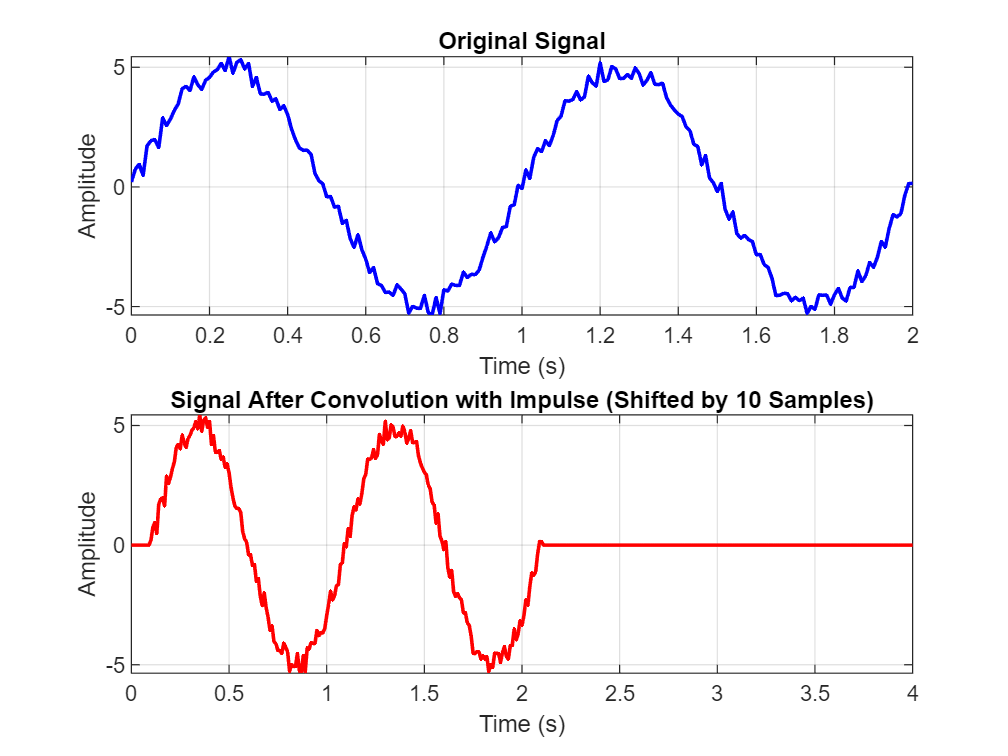

h_shift = zeros(1, N);  
h_shift(11) = 1;  
t_conv = 0:0.01:4;
shifted_signal = conv(noisy_x, h_shift); 

figure;
subplot(2,1,1);
plot(t, noisy_x, 'b', 'LineWidth', 1.5);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t_conv, shifted_signal, 'r', 'LineWidth', 1.5);
title('Signal After Convolution with Impulse (Shifted by 10 Samples)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

## Part4: filter function

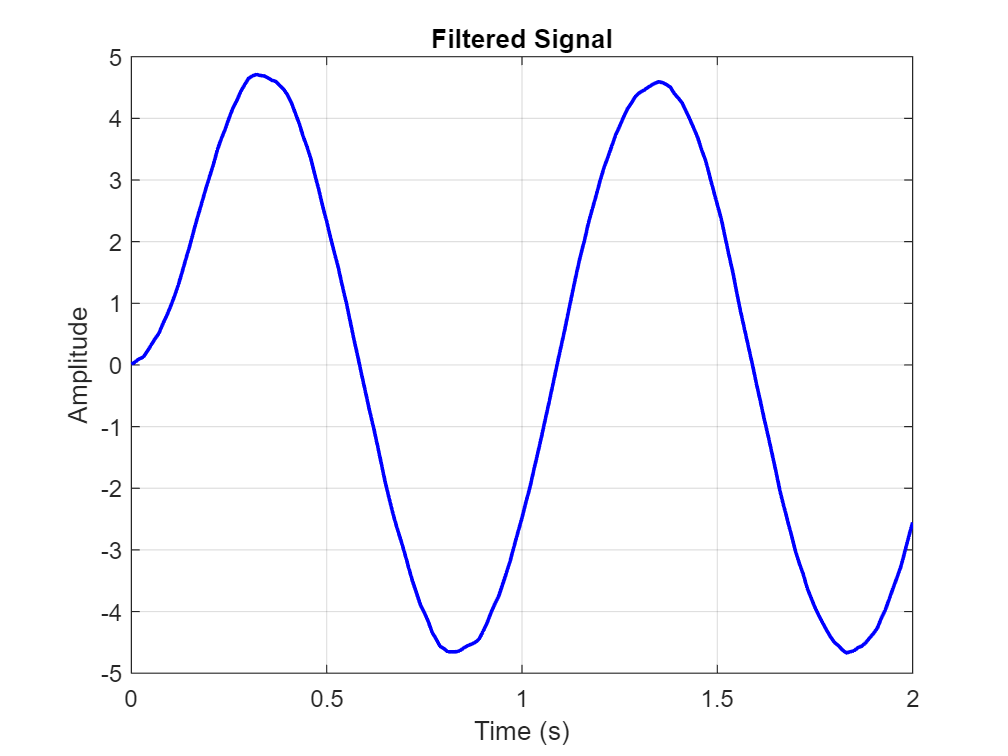

filtered_signal = filter(moving_avg,1,noisy_x);
figure("Name","using filter function");
plot(t, filtered_signal, 'b', 'LineWidth', 1.5);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

## Part 5: function definition

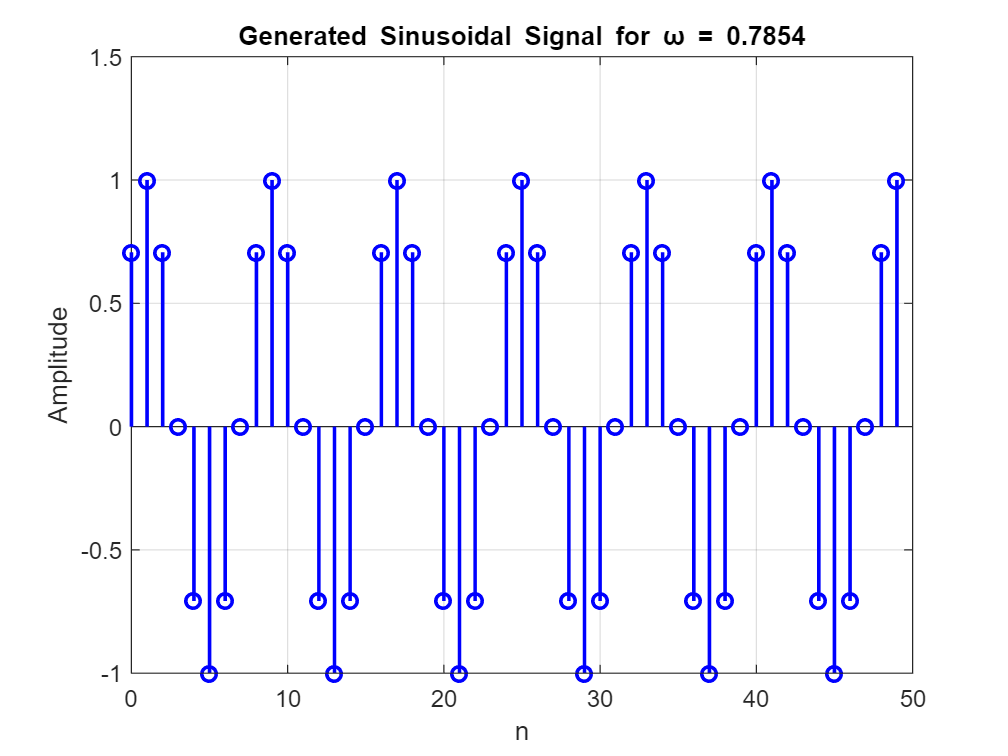

n = 50;  
omega = pi/4;  
x = singen(omega, n);

stem(0:n-1, x, 'b', 'LineWidth', 1.5);
xlabel('n'); ylabel('Amplitude');
title(['Generated Sinusoidal Signal for \omega = ', num2str(omega)]);
grid on;

function x = singen(omega, n)
    b = [sin(omega), 0];  
    a = [1, -2*cos(omega), 1];  

    delta = [1, zeros(1, n-1)];  

    x = filter(b, a, delta);
end